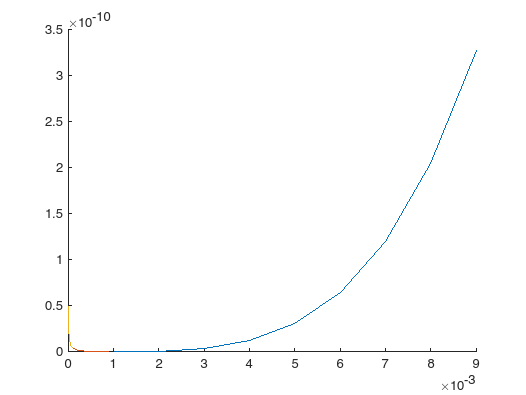

clear

hold on


startX = 0;
endX = 2;


% maxDevsX = [];
% maxDevsY = [];


H = 0.01;
endH = 0.00001;

while H > endH
    
    nextH = H * 0.1;

    maxDevsX = [];
    maxDevsY = [];

    for h = H-nextH:-nextH:nextH

        maxDev = 0;

        for j = 1:floor((endX - startX)/h)
            x = startX + (j-1)*h;
            curDev = abs(IV2(x, h) - df(x));
            if curDev > maxDev
                maxDev = curDev;
            end
        end

        maxDevsX = [maxDevsX, h];
        maxDevsY = [maxDevsY, maxDev];
    end

    plot(maxDevsX, maxDevsY)
    pause

    H = nextH;
end



% maxDevsX
% maxDevsY
% 
% plot(maxDevsX, maxDevsY)

function f = f(X)
    f = sin(X);
end

function df = df(X)
    df = cos(X);
end


function I1 = I1(x, h)
    I1 = (f(x+h) - f(x))/h;
end

function I2 = I2(x, h)
    I2 = (f(x) - f(x-h))/h;
end


function II1 = II1(x, h)
    II1 = (4*f(x+h) - 3*f(x) - f(x+2*h))/(2*h);
end

function II2 = II2(x, h)
    II2 = (f(x+h) - f(x-h))/(2*h);
end


function IV2 = IV2(x, h)
    IV2 = (f(x+3*h) - 6*f(x+2*h) + 18*f(x+h) - 10*f(x) - 3*f(x-h))/(12*h);
end

function IV3 = IV3(x, h)
    IV3 = (f(x-2*h) - 8*f(x-h) + 8*f(x+h) - f(x+2*h))/(12*h);
end